# BootCamp Control

## 1. Drone and plant parameters

m = 1.2;          % Overall mass (kg)
g = 9.81;         % Gravity (m/s^2)
num_motors = 4;   % Num of motors
c_t = 0.25;       % Thrust coeff (N / V^2)
c_d = 0.25;       % Drag coeff (N*s/m)
V_max = 16.0;     % Max voltage (V)
V_min = 0.0;      % Min voltage (V)

% Voltaje de equilibrio en Hover (Equilibrio: F_total = m*g)
% F_total = num_motores * c_t * (V_hover / num_motores)^2 = m * g
V_hover = num_motors * sqrt((m * g) / (num_motors * c_t));


## 2. PARÁMETROS DE CALIBRACIÓN PID Y SIMULACIÓN

% Ajusta estas constantes para calibrar la respuesta del dron:
Kp = 19;
Ki = 0.4;
Kd = 2.2;

dt = 0.01;        % Paso de integración (s)


## 3. ESCENARIO 1: HOVER (STEP 0 -> 10 m)

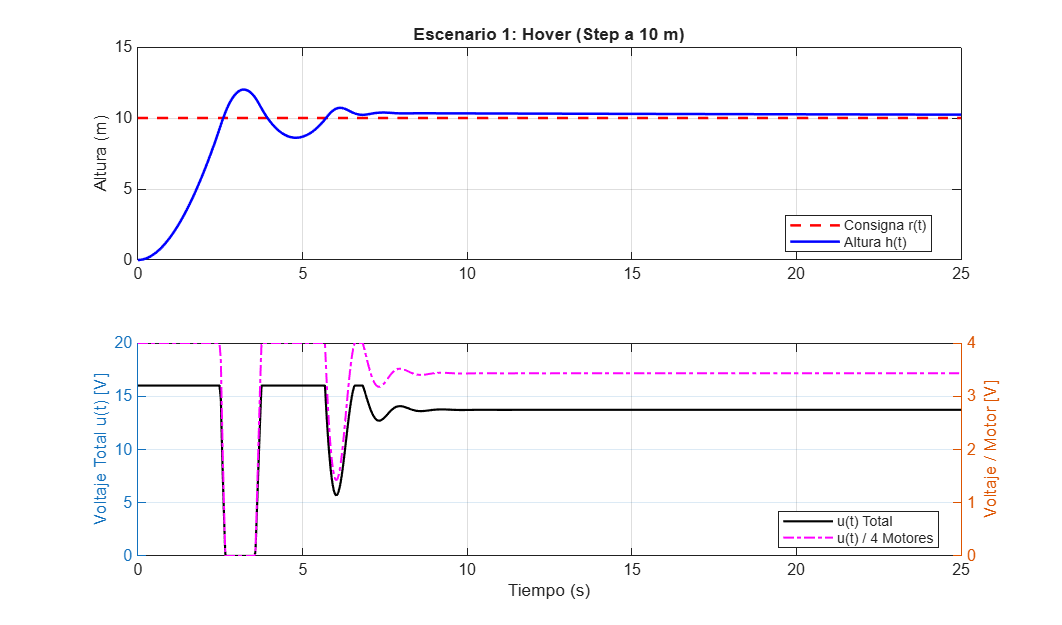

t1 = 0:dt:25;
r1 = 10 * ones(size(t1)); % Consigna escalón a 10 metros
[h1, u1, v_mot1] = simular_dron(t1, r1, Kp, Ki, Kd, V_hover, num_motors, c_t, c_d, m, g, V_min, V_max, dt);

graficar_respuesta(t1, r1, h1, u1, v_mot1, 'Escenario 1: Hover (Step a 10 m)');

## 4. ESCENARIO 2: SUBIDA MEDIA (STEP 0 -> 50 m)

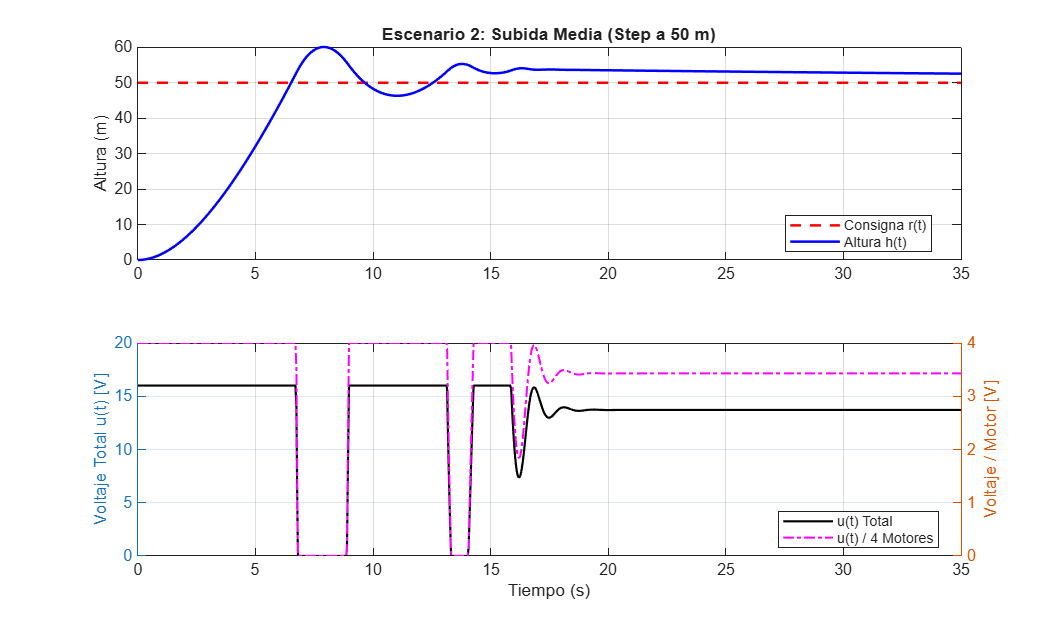

t2 = 0:dt:35;
r2 = 50 * ones(size(t2));
[h2, u2, v_mot2] = simular_dron(t2, r2, Kp, Ki, Kd, V_hover, num_motors, c_t, c_d, m, g, V_min, V_max, dt);

graficar_respuesta(t2, r2, h2, u2, v_mot2, 'Escenario 2: Subida Media (Step a 50 m)');

## 5. ESCENARIO 3: GRAN ALTITUD (STEP 0 -> 1000 m)

t3 = 0:dt:80;
r3 = 1000 * ones(size(t3));
[h3, u3, v_mot3] = simular_dron(t3, r3, Kp, Ki, Kd, V_hover, num_motors, c_t, c_d, m, g, V_min, V_max, dt);

error = max(h3) - max(r3);
if (error >= 0)
    fprintf("Overshoot: %.2f m", abs(error));
else
    fprintf("Undershoot: %.2f m", abs(error));
end

Overshoot: 271.95 m

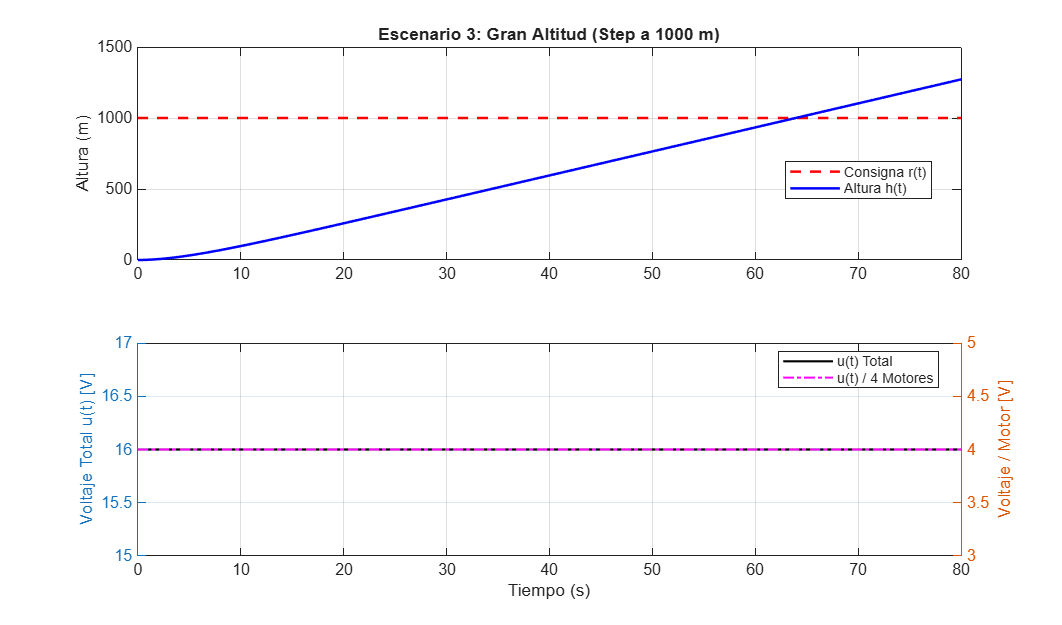

graficar_respuesta(t3, r3, h3, u3, v_mot3, 'Escenario 3: Gran Altitud (Step a 1000 m)');

## 6. ESCENARIO 4: REFERENCIA SENOIDAL (OSCILACIÓN ENTRE 100 Y 200 m)

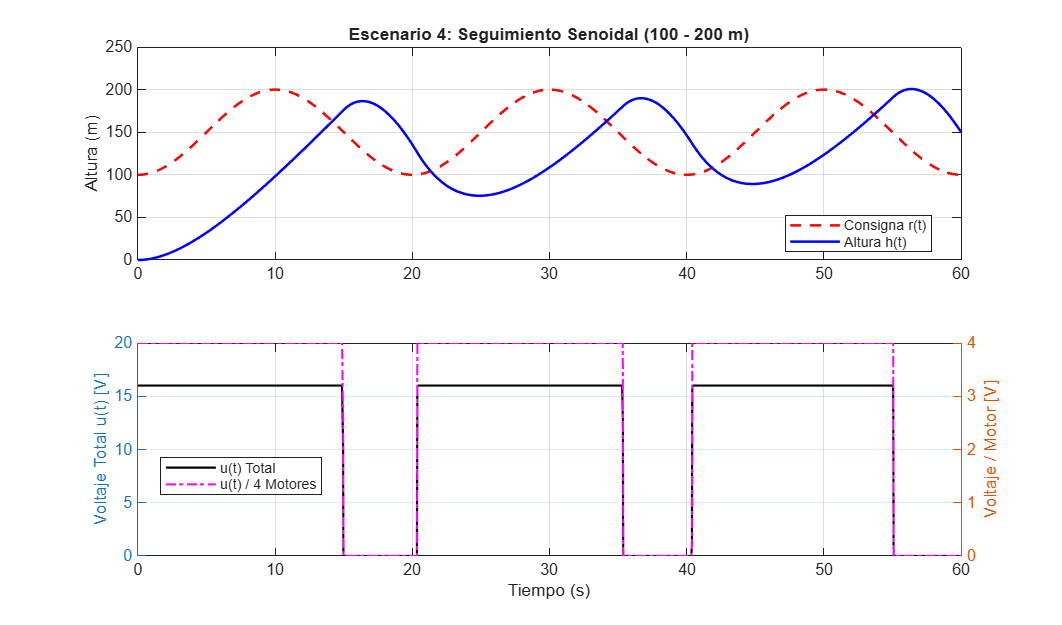

t4 = 0:dt:60;
freq_hz = 0.05; % Frecuencia de oscilación (Hz)
% r(t) oscila entre 100 m y 200 m (Amplitud 50 m, Offset 150 m):
r4 = 150 + 50 * sin(2 * pi * freq_hz * t4 - pi/2);
[h4, u4, v_mot4] = simular_dron(t4, r4, Kp, Ki, Kd, V_hover, num_motors, c_t, c_d, m, g, V_min, V_max, dt);

graficar_respuesta(t4, r4, h4, u4, v_mot4, 'Escenario 4: Seguimiento Senoidal (100 - 200 m)');

## FUNCIONES AUXILIARES (Simulación y Visualización)

function [h, u_tot, v_mot] = simular_dron(t, r, Kp, Ki, Kd, V_hover, n_mot, c_t, c_d, m, g, V_min, V_max, dt)
    N = length(t);
    h = zeros(1, N);       % Posición vertical / Altura (m)
    v = zeros(1, N);       % Velocidad vertical (m/s)
    u_tot = zeros(1, N);   % Voltaje total comandado (V)
    v_mot = zeros(1, N);   % Voltaje por motor individual (V)
    
    integral_err = 0;
    prev_err = 0;
    
    for i = 1:N-1
        err = r(i) - h(i);
        integral_err = integral_err + err * dt;
        deriv_err = (err - prev_err) / dt;
        
        % Señal de control PID + compensación del punto de equilibrio (Hover)
        u_raw = V_hover + (Kp * err + Ki * integral_err + Kd * deriv_err);
        
        % Saturación del voltaje total admisible
        u_sat = max(V_min, min(V_max, u_raw));
        
        % Reparto equitativo del voltaje entre los motores
        v_motor_i = u_sat / n_mot;
        
        % Empuje total generado por los motores
        empuje_total = n_mot * (c_t * (v_motor_i^2));
        
        % Ecuación de dinámica vertical (Segunda Ley de Newton)
        % m * a = F_empuje - m*g - F_arrastre
        a = (empuje_total - m * g - c_d * v(i)) / m;
        
        % Integración numérica (Euler hacia adelante)
        v(i+1) = v(i) + a * dt;
        h(i+1) = h(i) + v(i+1) * dt;
        
        % Restricción de contacto con el suelo
        if h(i+1) < 0
            h(i+1) = 0;
            v(i+1) = 0;
        end
        
        % Registro de señales
        u_tot(i) = u_sat;
        v_mot(i) = v_motor_i;
        prev_err = err;
    end
    u_tot(N) = u_tot(N-1);
    v_mot(N) = v_mot(N-1);
end

function graficar_respuesta(t, r, h, u_tot, v_mot, titulo)
    figure('Color', 'w', 'Position', [100, 100, 850, 500]);
    
    % Subplot 1: Altura vs Referencia
    subplot(2, 1, 1);
    plot(t, r, 'r--', 'LineWidth', 1.5); hold on;
    plot(t, h, 'b-', 'LineWidth', 1.5);
    grid on;
    ylabel('Altura (m)');
    legend('Consigna r(t)', 'Altura h(t)', 'Location', 'best');
    title(titulo);
    
    % Subplot 2: Voltaje Total Comandado y por Motor
    subplot(2, 1, 2);
    yyaxis left
    plot(t, u_tot, 'k-', 'LineWidth', 1.3);
    ylabel('Voltaje Total u(t) [V]');
    grid on;
    
    yyaxis right
    plot(t, v_mot, 'm-.', 'LineWidth', 1.2);
    ylabel('Voltaje / Motor [V]');
    
    xlabel('Tiempo (s)');
    legend('u(t) Total', 'u(t) / 4 Motores', 'Location', 'best');
end